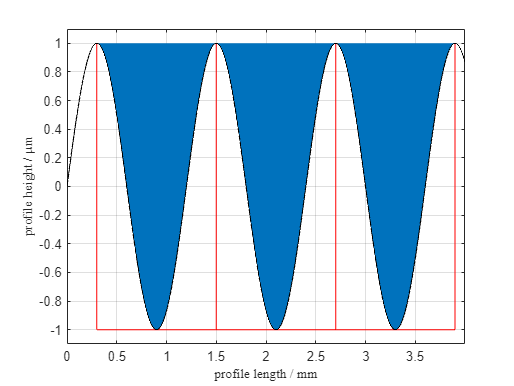

clc;clear;close all;
format long
dx = 0.5e-3;
load("..\..\data\profiles\simple_sin_1_open_peak.mat")
M = watershed_segmentation(z,dx,"D","Wolfprune",0.1);
figure
plot_motifs(z, dx, M);


HDhm = feature_parameter(z, dx, M, "All", 1, "HDh", "Mean");
HDhm_theo = 2;
HDwm = feature_parameter(z, dx, M, "All", 1, "HDw", "Mean");
HDwm_theo = 1.200;
HDvm = feature_parameter(z, dx, M, "All", 1, "HDv", "Mean");
syms x
f(x) = sin(2*pi*x/1200);
HDvm_theo = double(int(f(x) + 1, 0.300, 1.500)/(length(z)*dx));
HDlm = feature_parameter(z, dx, M, "All", 1, "HDl", "Mean");
l = int(sqrt(1+diff(f(x),x)^2),[300 1500]);
HDlm_theo = double(l/1000);
Rmvc = feature_parameter(z, dx, M, "All", 1, "Curvature", "Mean");
k(x) = diff(diff(f(x),x),x)/(1 + diff(f(x),x)^2)^(3/2);
Rmvc_theo = double(k(900));
% output table
T = table('Size', [1 4], 'VariableTypes', {'string','double','double','double'}, 'VariableNames',{'Parameter','Feature_Characterization','analytical solution','deviation in %'});
T(end, :) = {"Mean motif height", HDhm, HDhm_theo, abs(HDhm-HDhm_theo)*100/HDhm_theo};
T(end+1, :) = {"Mean motif width", HDwm, HDwm_theo, abs(HDwm-HDwm_theo)*100/HDwm_theo};
T(end+1, :) = {"Mean motif volume", HDvm, HDvm_theo, abs(HDvm-HDvm_theo)*100/HDvm_theo};
T(end+1, :) = {"Mean motif de. length", HDlm, HDlm_theo, abs(HDlm-HDlm_theo)*100/HDlm_theo};
T(end+1, :) = {"Mean motif pit curvature", Rmvc, Rmvc_theo, abs(Rmvc-Rmvc_theo)*100/Rmvc_theo}

T = 5×4 table
            Parameter             Feature_Characterization    analytical solution        deviation in %   
    __________________________    ________________________    ____________________    ____________________

    "Mean motif height"                                2                         2                       0
    "Mean motif width"                               1.2                       1.2                       0
    "Mean motif volume"                              0.3         0.301413709136351       0.469026156906322
    "Mean motif de. length"             1.20000822462336          1.20000822462806    3.91480459048935e-10
    "Mean motif pit curvature"      2.74155677817165e-05      2.74155677808038e-05    3.32911194334088e-09



load("..\..\data\profiles\sinus_04_zeros_04.mat")
M = watershed_segmentation(z, dx, "H", "Wolfprune", 0.1);
figure
plot_motifs(z,dx,M);
HDhm = feature_parameter(z, dx, M, "All", 1, "HDh", "Mean");
HDwm = feature_parameter(z, dx, M, "All", 1, "HDw", "Mean");
HDvm = feature_parameter(z, dx, M, "All", 1, "HDv", "Mean");
syms x
f(x)=sin(2*pi*x/800);
HDvm_theo = abs(double(int(f(x), 400, 800)/((length(z)-1)*dx)));
Rmvc = feature_characterization(z, dx, "V", "Wolfprune 0.1", "All", "Curvature", "Mean");
Rmpc = feature_characterization(z, dx, "P", "Wolfprune 0.1", "All", "Curvature", "Mean");

% Pits are plateaus with 2 points with same height!
syms x
f(x)=sin(2*pi*x/800);
k(x)=diff(diff(f(x),x),x)/(1 + diff(f(x),x)^2)^(3/2);
Rmvc_theo = double(k(600));
clear T
T(1) = struct('parameter',"Mean motif height",'Feature_Characterization',HDhm,'theoretical_value',max(z) -min(z));
T(2) = struct('parameter',"Mean motif width",'Feature_Characterization',HDwm,'theoretical_value',HDwm_theo);
T(3) = struct('parameter',"Mean motif volume",'Feature_Characterization',HDvm,'theoretical_value',HDvm_theo);
T(4) = struct('parameter',"Mean motif dev. length",'Feature_Characterization',HDlm,'theoretical_value',HDlm_theo);
T(5) = struct('parameter',"Mean motif pit curvature",'Feature_Characterization',Rmvc,'theoretical_value',Rmvc_theo);
T(6) = struct('parameter',"Mean motif peak curvature",'Feature_Characterization',Rmpc,'theoretical_value',0);
T

load("..\..\data\profiles\kuppen_taeler_4mm.mat")
figure
M = watershed_segmentation(z,dx,"D","Wolfprune",0.1);
figure
plot_motifs(z,dx,M);
HDvx = feature_parameter(z, dx, M, "All", 1, "HDv", "Max")
syms x
f(x)=-sin(2*pi*x/800);
HDvm_theo = double(int(f(x), 0, 400))
HDvmin = feature_parameter(z, dx, M, "All", 1, "HDv", "Min")
HDvm_theo = 2*double(int(f(x)+1, 0, 200))
HDhm = feature_parameter(z, dx, M, "All", 1, "HDh", "Mean")
HDwm = feature_parameter(z, dx, M, "All", 1, "HDw", "Mean")
Rmpc = feature_parameter(z, dx, M, "All", 1, "Curvature", "Mean")
Rmvc = feature_parameter(z, dx, M, "All", 1, "Curvature", "Mean")

load("..\..\data\profiles\Luftpresser_1_56_ak.mat")
M = watershed_segmentation(z, dx, "D","Wolfprune", 0.5);
figure
plot_motifs(z,dx,M);
HDvm = feature_parameter(z, dx, M, "All", 1, "HDv", "Mean")
HDhm = feature_parameter(z, dx, M, "All", 1, "HDh", "Mean")
HDwm = feature_parameter(z, dx, M, "All", 1, "HDw", "Mean")
Rmpc = feature_parameter(z, dx, M, "All", 1, "Curvature", "Mean")
Rmvc = feature_parameter(z, dx, M, "All", 1, "Curvature", "Mean")

load("..\..\data\profiles\zeros_kuppen_taeler.mat")
M = watershed_segmentation(z,dx,"D","Wolfprune",0.1);
figure
plot_motifs(z,dx,M);
HDvm = feature_parameter(z, dx, M, "All", 1, "HDv", "Mean")
HDhm = feature_parameter(z, dx, M, "All", 1, "HDh", "Mean")
HDwm = feature_parameter(z, dx, M, "All", 1, "HDw", "Mean")
Rmpc = feature_parameter(z, dx, M, "All", 1, "Curvature", "Mean")
Rmvc = feature_parameter(z, dx, M, "All", 1, "Curvature", "Mean")

load("..\..\data\profiles\tstRSm_random.mat")
M = watershed_segmentation(z, dx, "D", "Wolfprune", 0.1);
figure
plot_motifs(z,dx,M);
HDvm = feature_parameter(z, dx, M, "All", 1, "HDv", "Mean")
HDhm = feature_parameter(z, dx, M, "All", 1, "HDh", "Mean")
HDwm = feature_parameter(z, dx, M, "All", 1, "HDw", "Mean")
Rmpc = feature_parameter(z, dx, M, "All", 1, "Curvature", "Mean")
Rmvc = feature_parameter(z, dx, M, "All", 1, "Curvature", "Mean")

load("..\..\data\profiles\sinus_04_sinus_04.mat")
M = watershed_segmentation(z,dx,"D","Wolfprune",0.1);
figure
plot_motifs(z,dx,M);
HDvm = feature_parameter(z, dx, M, "All", 1, "HDv", "Mean")
HDhm = feature_parameter(z, dx, M, "All", 1, "HDh", "Mean")
HDwm = feature_parameter(z, dx, M, "All", 1, "HDw", "Mean")
Rmpc = feature_parameter(z, dx, M, "All", 1, "Curvature", "Mean")
Rmvc = feature_parameter(z, dx, M, "All", 1, "Curvature", "Mean")

load("..\..\data\profiles\Bu_1_56_ak.mat")
M = watershed_segmentation(z, dx, "D", "Width", 60);
figure
plot_motifs(z,dx,M);
HDvm = feature_parameter(z, dx, M, "All", 1, "HDv", "Mean")
HDhm = feature_parameter(z, dx, M, "All", 1, "HDh", "Mean")
HDwm = feature_parameter(z, dx, M, "All", 1, "HDw", "Mean")
RSm = 182; % 
Rmpc = feature_parameter(z, dx, M, "All", 1, "Curvature", "Mean")
Rmvc = feature_parameter(z, dx, M, "All", 1, "Curvature", "Mean")
